# RoadRunner - Simulinkのcosimulationによるセンサモデルの活用　（オブサーバ）

# R2024b以降での実行が必要

## 変数、RoadRunnerをクリーンアップ

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;

## RoadRunnerをMATLABから起動し、ObserverとしてSimulinkモデルを設定する

Observerとして設定した場合、Simulinkは車両位置をRoadRunnerに返す必要がない

[addObserver](https://jp.mathworks.com/help/driving/ref/matlab.system.addobserver.html#mw_a615e75e-3e93-4b9d-91fb-dfb6d4099673)　関数でSimulinkモデルをObserverとして追加

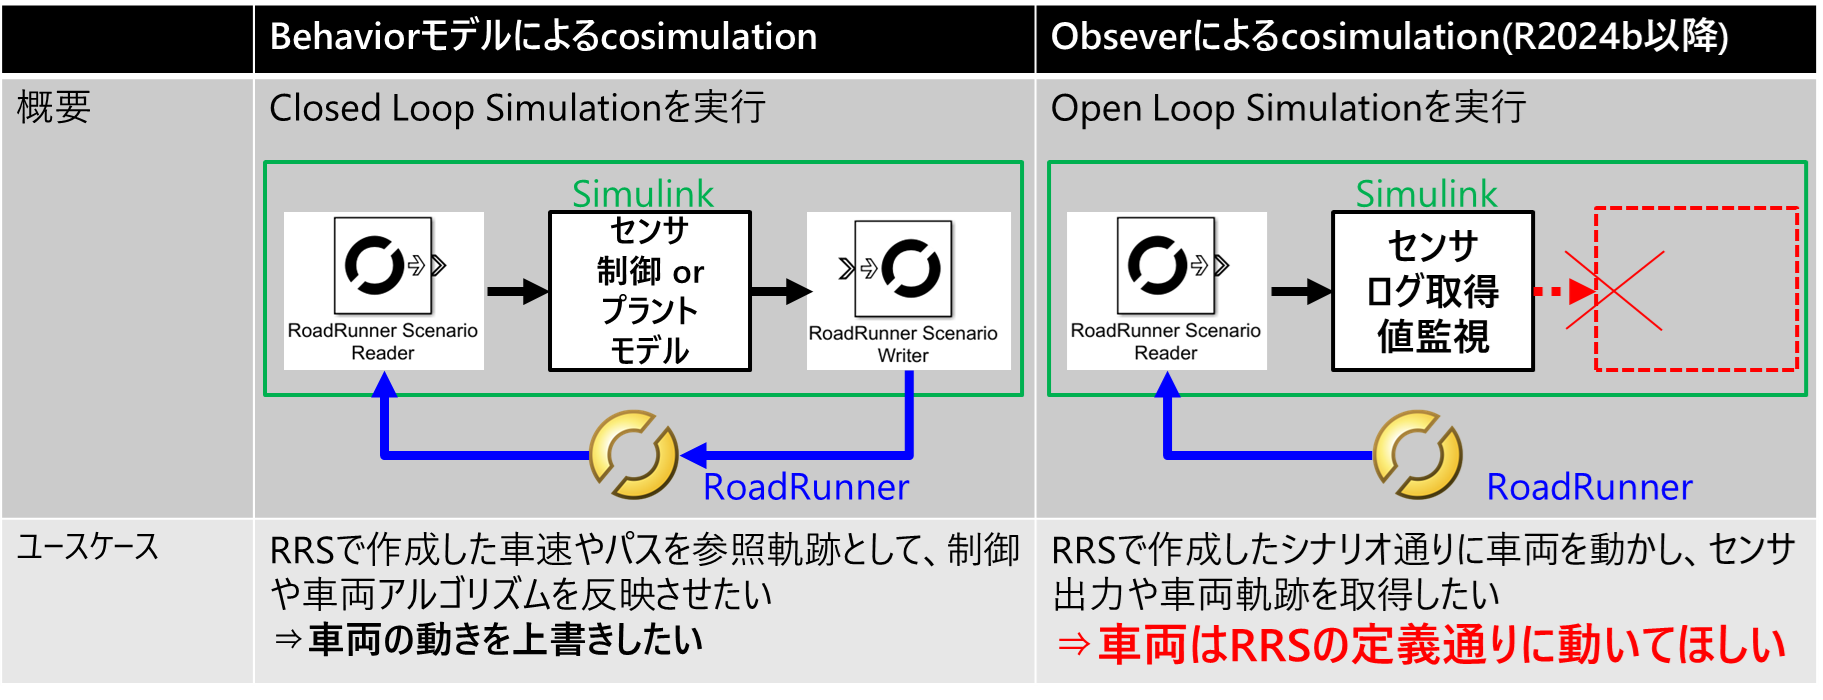

rrApp = roadrunner();

% シナリオを起動　シーンはシナリオと紐づいているため、自動でシーンも開く
rrApp.openScenario("TrajectoryCutIn");

% RoadRunnerとSimulinkの実行ステップサイズを揃える
simStepSize = 0.1;
rrSim = rrApp.createSimulation();
setRRSCameraMode(rrApp, "follow", actorID=1);
rrSim.set("StepSize", simStepSize);

% RoadRunnerの情報をSimulinkで取得するため、Busオブジェクトを定義
% To support Reader and Writer blocks, some bus objects must be loaded
load(fullfile(matlabroot,'toolbox','driving','drivingdata','rrScenarioSimTypes.mat'));
load("busDefinitionsForRRSim.mat"); % sensor simulation用のバスオブジェクトを読出し

addpath("pathFollowingUtil");
% Simulinkのモデルを開く
model_name = 'SensorSimulinkVehicleObserver';
open_system(model_name);

% ObserverとしてSimulinkモデルを追加
addObserver(rrSim, "Ego", model_name + ".slx");

% Simulationを開始する
set(rrSim, "PacerStatus", "Off");
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end